# 03A. Nullclines

## Mingyang Lu

## 1/7/2024

### A two-variable toggle switch circuit


$$\begin{cases} \frac{dX}{dt} = g_{X0} + g_{X1}\frac{1}{1+(Y/Y_{th})^{n_Y}} - k_XX \\
              \frac{dY}{dt} = g_{Y0} + g_{Y1}\frac{1}{1+(X/X_{th})^{n_X}} - k_YY \end{cases}$$


 We perform ODE simulations from 10 differemt initial conditions.

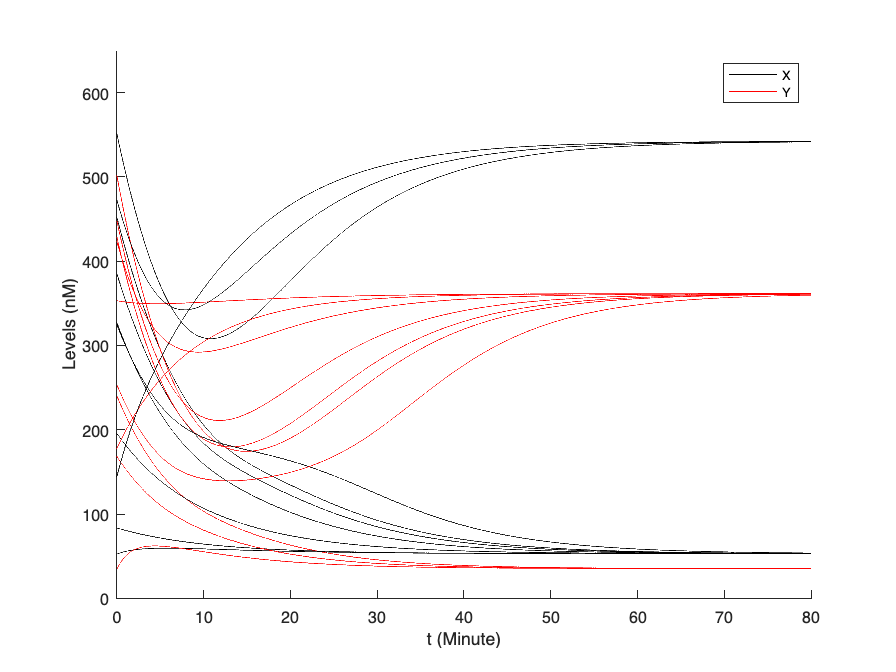

% set the seed for the random number generator
rng(77);
X_init_all = rand(10, 2) * 600; % generate 10 random initial conditions

t_total = 100;
dt = 0.01;
figure;
xlabel('t (Minute)');
ylabel('Levels (nM)');
xlim([0, 80]);
ylim([0, 650]);
hold on;

for i = 1:10
    results = RK4_generic(@derivs_ts, X_init_all(i, :), t_total, dt);
    plot(results(:, 1), results(:, 2), 'k', 'DisplayName', 'X' , 'Color', [0, 0, 0]);
    plot(results(:, 1), results(:, 3), 'r', 'DisplayName', 'Y' , 'Color', [1, 0, 0]);
end

legend('X', 'Y', 'Location', 'northeast', 'FontSize', 8);
hold off;

### Phase plane

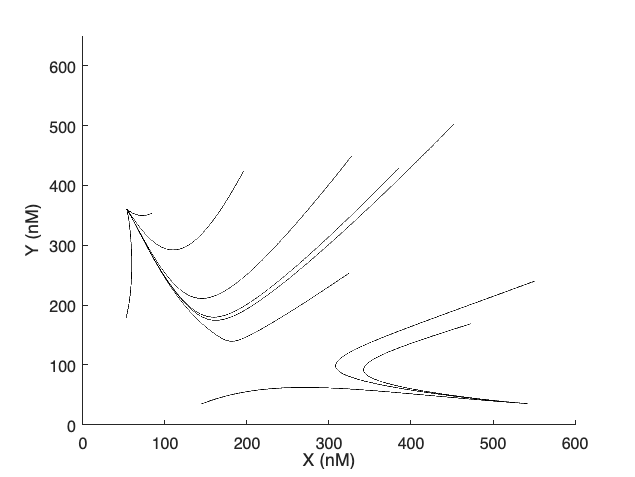

figure('Units', 'inches', 'Position', [0, 0, 5, 5]); % Adjust the figure size to maintain a 1:1 aspect ratio
xlabel('X (nM)');
ylabel('Y (nM)');
xlim([0, 600]);
ylim([0, 650]);
hold on;

for i = 1:10
    results = RK4_generic(@derivs_ts, X_init_all(i, :), t_total, dt);
    plot(results(:, 2), results(:, 3), 'k'); % Plot X vs Y with black color
end
hold off;

### Vector field

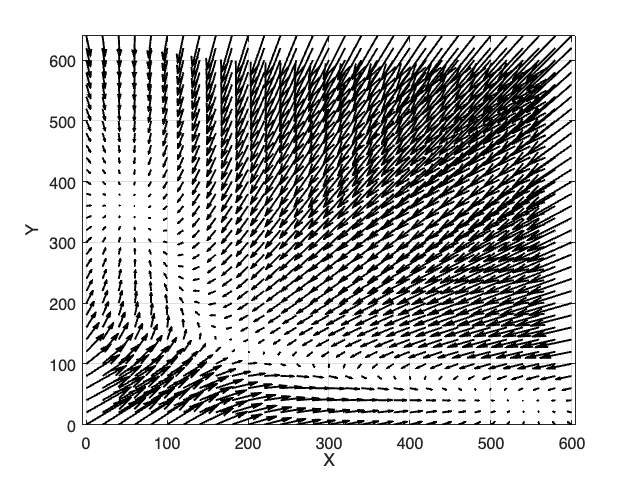

X_all = 0:20:600;  % all X grids
Y_all = 0:20:650;  % all Y grids
[X_all, Y_all] = meshgrid(X_all, Y_all);  % all combinations of X and Y

XY_all = [X_all(:), Y_all(:)];  % reshape the array into a 2D array with 2 columns

% Function to generate vector field
generate_vector_field = @(Xs) [Xs(1), Xs(2), derivs_ts(0, Xs')];

% Apply the function along the specified axis
results = zeros(size(XY_all, 1), 4);
for i = 1:size(XY_all, 1)
    results(i, :) = generate_vector_field(XY_all(i, :));
end

figure('Units', 'inches', 'Position', [0, 0, 5, 5]);
quiver(results(:, 1), results(:, 2), results(:, 3), results(:, 4), 0, 'Color', 'black', 'LineWidth', 1.2);

xlabel('X');
ylabel('Y');
axis equal;
grid on;

#### Unit vector field

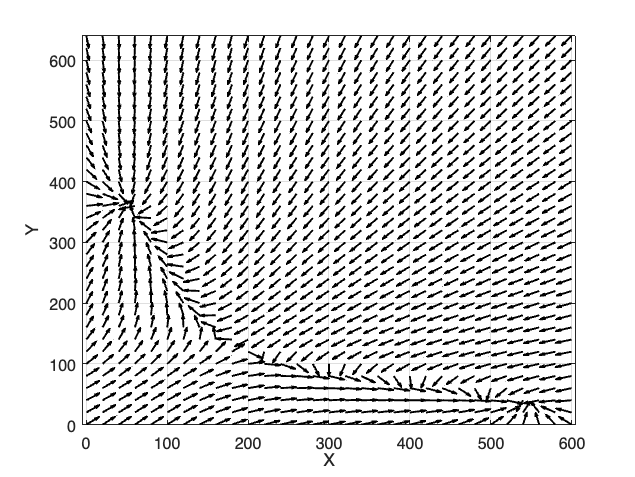

% Apply the function along the specified axis
results_unit = zeros(size(XY_all, 1), 4);
for i = 1:size(XY_all, 1)
    results_unit(i, :) = generate_normalized_vector_field(@derivs_ts, ...
        XY_all(i, :), 20);
end

figure('Units', 'inches', 'Position', [0, 0, 5, 5]);
quiver(results_unit(:, 1), results_unit(:, 2), ...
    results_unit(:, 3), results_unit(:, 4), ...
    0, 'Color', 'black', 'LineWidth', 1.2);

xlabel('X');
ylabel('Y');
axis equal;
grid on;

### Nullclines

#### 1. Separation of variables

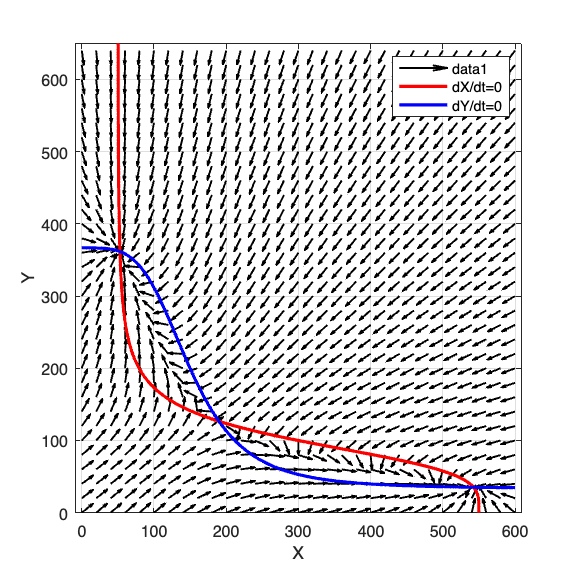

X_all = 0:1:600;  % all X grids
Y_all = 0:1:650;  % all Y grids

% Define nullcline functions
nullcline1 = @(Y) [(5 + 50 * hill_inh(Y, 100, 4))/ 0.1; Y].';
nullcline2 = @(X) [X; (4 + 40 * hill_inh(X, 150, 4)) / 0.12].';

% Calculate nullclines
null1 = nullcline1(Y_all);
null2 = nullcline2(X_all);

% Plot unit vector field
figure('Units', 'inches', 'Position', [0, 0, 5, 5]);
quiver(results_unit(:, 1), results_unit(:, 2), ...
    results_unit(:, 3), results_unit(:, 4), ...
    0, 'Color', 'black', 'LineWidth', 1.2);
hold on;

% Plot nullclines
plot(null1(:, 1), null1(:, 2), 'r', 'LineWidth', 2, 'DisplayName', 'dX/dt=0');
plot(null2(:, 1), null2(:, 2), 'b', 'LineWidth', 2, 'DisplayName', 'dY/dt=0');

xlabel('X');
ylabel('Y');
legend('Location', 'northeast');
axis equal;
grid on;
hold off;

#### 2. Contour method

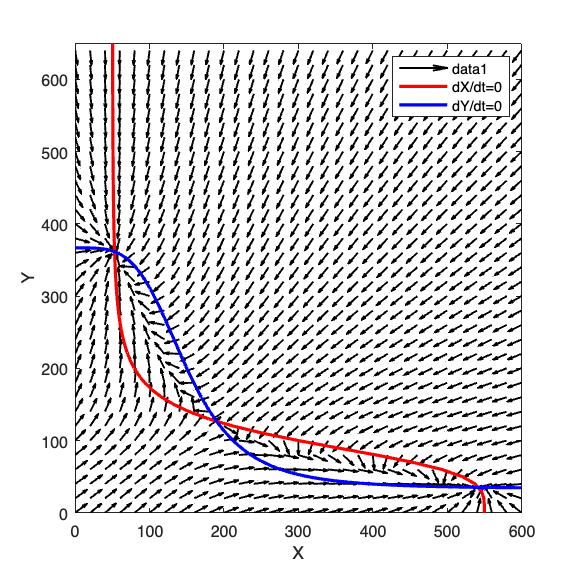

X_all = 0:10:600;
Y_all = 0:10:650;
nX = length(X_all);
nY = length(Y_all);
% all combinations of X and Y
[X_all, Y_all] = meshgrid(X_all, Y_all);

XY_all = [X_all(:), Y_all(:)]; 

% Apply the function along the specified axis
results = zeros(size(XY_all, 1), 4);
for i = 1:size(XY_all, 1)
    results(i, :) = generate_vector_field(XY_all(i, :));
end

% Note the transposition to match the shape of meshgrid
z_X = reshape(results(:, 3), nY, nX);
z_Y = reshape(results(:, 4), nY, nX);

% Plot unit vector field
figure('Units', 'inches', 'Position', [0, 0, 5, 5]);
quiver(results_unit(:, 1), results_unit(:, 2), ...
    results_unit(:, 3), results_unit(:, 4), ...
    0, 'Color', 'black', 'LineWidth', 1.2);
hold on;

% Plot contour for z_X (x-nullcline)
contour_plot_X = contour(X_all, Y_all, z_X, 'LevelList', [0], ...
    'LineColor', 'red', 'LineWidth', 2, 'DisplayName', 'dX/dt=0');

% Plot contour for z_Y (y-nullcline)
contour_plot_Y = contour(X_all, Y_all, z_Y, 'LevelList', [0], ...
    'LineColor', 'blue', 'LineWidth', 2, 'DisplayName', 'dY/dt=0');

xlabel('X');
ylabel('Y');
legend('Location', 'northeast');
hold off;

#### 3. Continuation method

(Omitted. Check Part 02E for a similar usage in generating bifurcation diagram)

Finally, save nullcline data (two matrices) to data file.

% Save the matrix to a CSV file
csvwrite('null1_03A.csv', null1);
csvwrite('null2_03A.csv', null2);

### Define MATLAB functions

1. Inhibitory Hill function

function out = hill_inh(a, X_th, n)
    out = 1 ./ (1 + (a ./ X_th).^n);
end

2. Derivative function for a toggle switch circuit

function result = derivs_ts(t, Xs)
    X = Xs(1);
    Y = Xs(2);
   
    dxdt = 5 + 50 * hill_inh(Y, 100, 4) - 0.1 * X;
    dydt = 4 + 40 * hill_inh(X, 150, 4) - 0.12 * Y;
    
    result = [dxdt, dydt];
end

3. RK4 ODE integrator for a multiple-variable system.

function results = RK4_generic(derivs, X0, t_total, dt, varargin)
    % 4th order Runge-Kutta (RK4) for a generic multi-variable system
    % derivs: the function of the derivatives
    % X0: initial condition, a list of multiple variables
    % t_total: total simulation time, assuming t starts from 0 at the beginning
    % dt: time step size
    t_all = 0:dt:t_total;
    n_all = length(t_all);
    nx = length(X0);
    X_all = zeros(n_all, nx);
    X_all(1, :) = X0;
    for i = 1:(n_all - 1)
        t_0 = t_all(i);
        t_0_5 = t_0 + 0.5 * dt;
        t_1 = t_0 + dt;
        k1 = dt * derivs(t_0, X_all(i, :), varargin{:});
        k2 = dt * derivs(t_0_5, X_all(i, :) + k1 / 2, varargin{:});
        k3 = dt * derivs(t_0_5, X_all(i, :) + k2 / 2, varargin{:});
        k4 = dt * derivs(t_1, X_all(i, :) + k3, varargin{:});
        X_all(i + 1, :) = X_all(i, :) + (k1 + 2 * k2 + 2 * k3 + k4) / 6;
    end
    results = [t_all', X_all];
end

4. Generate unit vector field

% Define function to generate normalized vector field
function vector = generate_normalized_vector_field(derivs, Xs, scale)
    df = derivs(0, Xs);
    df_norm = scale * df/norm(df);
    vector = [Xs, df_norm];
end